# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 5: exercise 03 - Kmeans

La base de datos `fisheriris` consiste en mediciones de (1) la longitud del sépalo, (2) la anchura del sépalo, (3) la longitud del pétalo y (4) la anchura del pétalo para 150 especímenes de iris (el iris es un conjunto de especies de plantas con flores llamativas). Hay 50 especímenes de cada una de las tres especies {`setosa, versicolor y virginica`}.

clc;
clear all;
close all;

Step 1) Carga datos

load fisheriris
data_iris = meas(:,1:2);
label_iris = categorical(species);
names_iris = categories(label_iris);

Step 2) Visualiza datos.

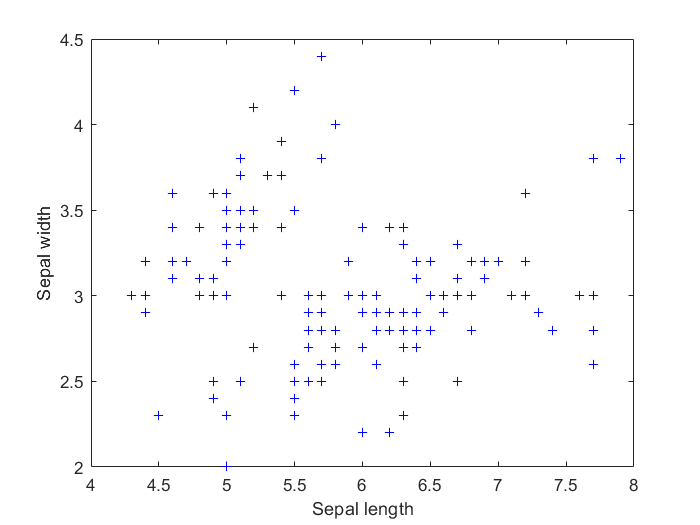

plot(data_iris(:,1),data_iris(:,2),'b+','MarkerSize',5);
xlabel('Sepal length');
ylabel('Sepal width');

Step 3) Kmeans

k = 3; % clusters

% 'Start', 'sample': toma los centroides de forma aleatoria de entre las muestras
%     'MaxIter',100: número máximo de iteraciones
% 'Display', 'iter': muestra los valores intermedios

% idx: indices de pertenencia a los k clusters
%   C: centroides de los k clusters

[idx,C] = kmeans(data_iris, k, 'Start', 'sample','MaxIter',100, 'Display', 'iter');

  iter	 phase	     num	         sum
     1	     1	     150	     67.9588
     2	     1	      14	     51.9139
     3	     1	      12	     49.5513
     4	     1	       8	     47.8565
     5	     1	       9	     45.7454
     6	     1	       6	     44.3507
     7	     1	       5	     43.6064
     8	     1	      10	     41.3302
     9	     1	       9	      38.958
    10	     1	       5	     38.1383
    11	     1	       5	     37.6193
    12	     1	       3	     37.3036
    13	     1	       2	     37.0877
    14	     1	       1	     37.0507
Best total sum of distances = 37.0507


Hay que tener en cuenta que este es un algoritmo no supervisado por lo que las etiquetas pueden estar desordenadas. Los datos de entrada (`data_iris`) están ordenados siguiendo la siguiente distribución: los primero 50 datos son `'setosa'`, los 50 siguientes son `'versicolor'` y los últimos 50 son `'virginica'`. Para ordenar las etiquetas se va a utilizar el siguiente código, donde se va suponer que el clasificador **k-means** ha hecho un buen trabajo y el valor que más se repite (la moda) entre los primeros 50 datos es `'setosa'`, en los siguientes 50 datos es`'versicolor'` y en los últimos 50 es`'virginica'`. 

setosa_idx = mode(idx(1:50));
versicolor_idx = mode(idx(51:100));
virginica_idx = mode(idx(101:150));

label_kmeans = categorical(idx,[setosa_idx versicolor_idx virginica_idx],{'setosa' 'versicolor' 'virginica'});

Step 4) Plot clustering.

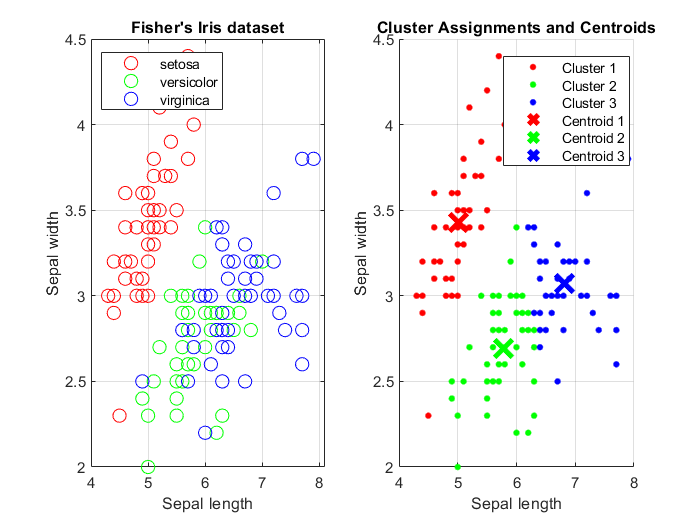

% Fisher''s Iris dataset
figure;
subplot(1,2,1)
gscatter(data_iris(:,1),data_iris(:,2), label_iris,'rgb','ooo',8,'on')
xlabel('Sepal length');
ylabel('Sepal width');
grid on;
legend('setosa','versicolor', 'virginica' ,'Location','NW')
title ('Fisher''s Iris dataset')

% K-Means clustering
subplot(1,2,2)
hold on
plot(data_iris(idx==setosa_idx,1),data_iris(idx==setosa_idx,2),'r.','MarkerSize',12)
plot(data_iris(idx==versicolor_idx,1),data_iris(idx==versicolor_idx,2),'g.','MarkerSize',12)
plot(data_iris(idx==virginica_idx,1),data_iris(idx==virginica_idx,2),'b.','MarkerSize',12)
plot(C(setosa_idx,1),C(setosa_idx,2),'rx','MarkerSize',15,'LineWidth',3) 
plot(C(versicolor_idx,1),C(versicolor_idx,2),'gx','MarkerSize',15,'LineWidth',3) 
plot(C(virginica_idx,1),C(virginica_idx,2),'bx','MarkerSize',15,'LineWidth',3) 
xlabel('Sepal length');
ylabel('Sepal width');
grid on;

legend('Cluster 1','Cluster 2','Cluster 3','Centroid 1','Centroid 2','Centroid 3','Location','best')
title ('Cluster Assignments and Centroids')
hold off

Se pide:

- Explique los resultados que obtiene el algoritmo k-means en cada iteración. ¿qué representa `iter`, `num`  y `sum`?

- Calcule la matriz de confusión del algoritmo K-means usando la función `confusionmat.` Si lo desea puede mostrarla gráficamente con la función `confusionchart`.

- Calcular la precisión (**acc=aciertos/total**) del algoritmo K-means.

- Repita las secciones anteriores pero usando pétalos en lugar de sépalos (`data_iris = meas(:,3:4);`). ¿En qué caso se obtienen mejores resultados?